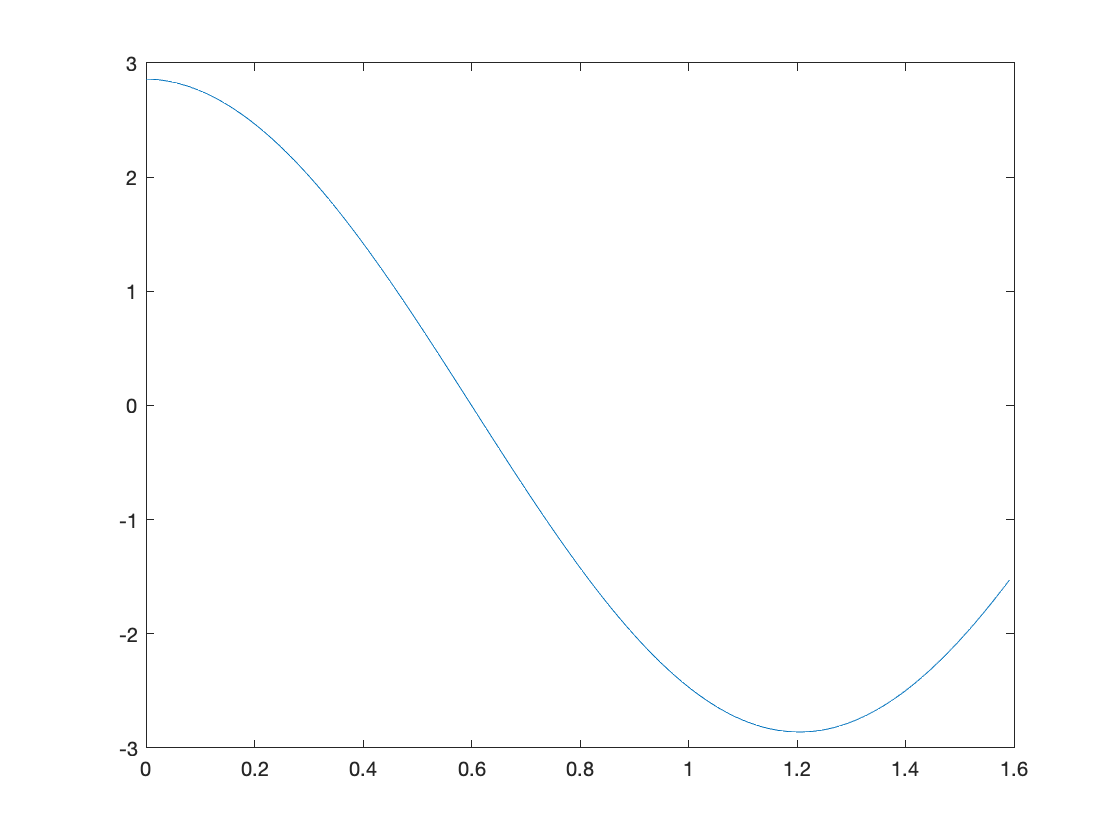

q =          0    0.0010    0.0020    0.0030    0.0040    0.0051    0.0061    0.0071    0.0081    0.0091    0.0101    0.0111    0.0121    0.0131    0.0141    0.0152    0.0162    0.0172    0.0182    0.0192    0.0202    0.0212    0.0222    0.0232    0.0242    0.0253    0.0263    0.0273    0.0283    0.0293    0.0303    0.0313    0.0323    0.0333    0.0343    0.0354    0.0364    0.0374    0.0384    0.0394    0.0404    0.0414    0.0424    0.0434    0.0444    0.0455    0.0465    0.0475    0.0485    0.0495


% ------------------------------------------------------
A     = 1.1; % fluorescence intensity units
omega = 2.6; % rad/s
A_0   = 0.01;

u=@(t) A*sin(omega*t)+A_0;

tArray = linspace(0,1.6,200);
uArray = u(tArray); % an array of samples of u
% ------------------------------------------------------

% analytical solutions (in real life, we might not know these)
dudtExact      =  A*omega*cos(omega*tArray);
du2dt2Exact    = -A*omega^2*sin(omega*tArray);
du3dt3Exact    = -A*omega^3*cos(omega*tArray);

%loop through noise size to detemine where 10% cutoff is
%give a variable name "z" to constant
%display(uObserved);

%figure;
%plot(tArray,uObserved, '+')
z = 1e-7;
uObserved = u(tArray) + z*randn(size(tArray));

%part 1
dudt = diff(uObserved)./diff(tArray);
du2dt2 = diff(dudt)./diff(tArray(1:end-1));
du3dt3 = diff(du2dt2)./diff(tArray(1:end-2));

plot(tArray(1:end-1), dudt)
q = linspace(0,0.1,100)
for i=1:100
    z = q(i);
    uObserved = u(tArray) + z*randn(size(tArray));
    dudt = diff(uObserved)./diff(tArray);
    du2dt2 = diff(dudt)./diff(tArray(1:end-1));
    du3dt3 = diff(du2dt2)./diff(tArray(1:end-2));
    diff1 = (dudt - dudtExact(1:end-1))./dudtExact(1:end-1);
    diff2 = (du2dt2 - du2dt2Exact(1:end-2))./du2dt2Exact(1:end-2);
    diff3 = (du3dt3 - du3dt3Exact(1:end-3))./du3dt3Exact(1:end-3);
        if max(abs(diff1))>0.1 || max(abs(diff2))>0.1 || max(abs(diff3))>0.1
                display(z)
                break
        end
end